# Velocity Distribution Function

First run the tracing program to get the cell `center`.

ACTIVATEPLOT=false;
folder="../asset/";
baseName="order";
Tracing

finished.
Elapsed time is 61.514299 seconds.


ans =    299     1


centerArray=zeros([sampleSize,sourceCount,2]);
velocity=zeros([sampleSize-1,sourceCount,2]);
centerArray(1,:,:)=center{1};
% FIXME: There might be NaNs, be careful about how to deal with them.
for i=2:sampleSize
    centerArray(i,:,:)=center{i};
    velocity(i-1,:,:)=centerArray(i,:,:)-centerArray(i-1,:,:); % unit in pixels.
end

Configure time interval and scaling.

frameRate=25;
dt=1/frameRate;
scaling=1; % unit: mm/pixel, remains to be calibrated.
velocity=velocity*frameRate*scaling;

vx=velocity(:,:,1);
vy=velocity(:,:,2);
speed=arrayfun(@norm,vx,vy);

Let's first take a look into the velocity and speed distribution at certain instant.

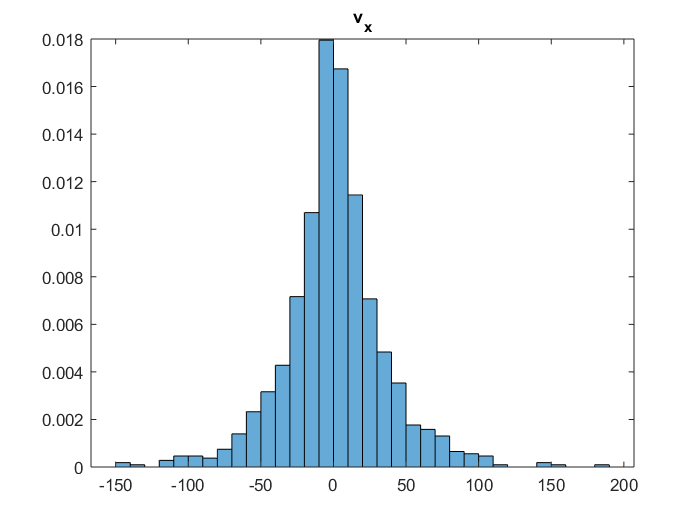

index=1;
figure;
histogram(vx(index,:),'Normalization','pdf');
title("v_x");

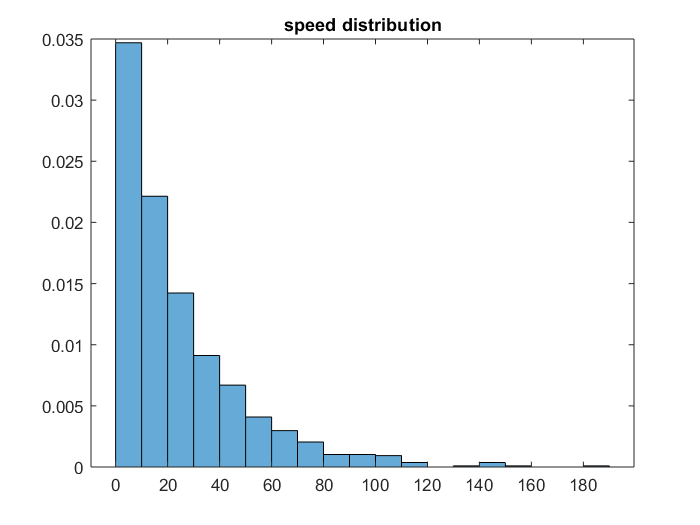

figure;
histogram(speed(index,:),'Normalization','pdf');
title("speed distribution");

To increase the population, combine all velocity in all instants together.

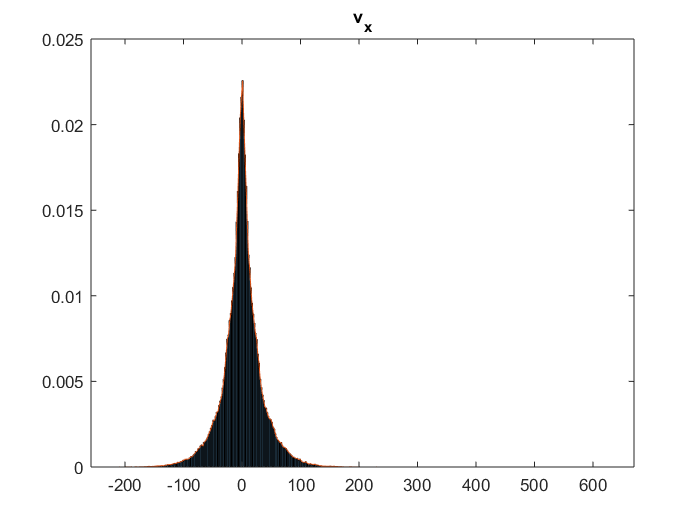

vxAll=reshape(vx,1,[]);
vyAll=reshape(vy,1,[]);
speedAll=arrayfun(@norm,vxAll,vyAll);
figure;
hV=histogram(vxAll,'Normalization','pdf');
PDVx=hV.Values;edgesV=hV.BinEdges; % probability density
hold on;
plot((edgesV(1:end-1)+edgesV(2:end))/2,PDVx); % locate at the center of bin.
title("v_x");

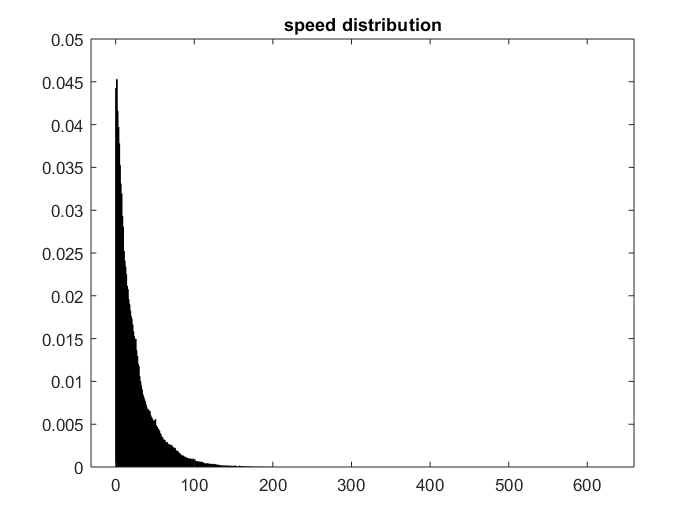

figure;
hS=histogram(speedAll,'Normalization','pdf');
hold on;
% [Ns,edgesS]=histcounts(speedAll,'Normalization','pdf');
Ns=hS.Values;edgesS=hS.BinEdges;
title("speed distribution");
hold off;

Fit and compare the distribution with Gaussian distribution.

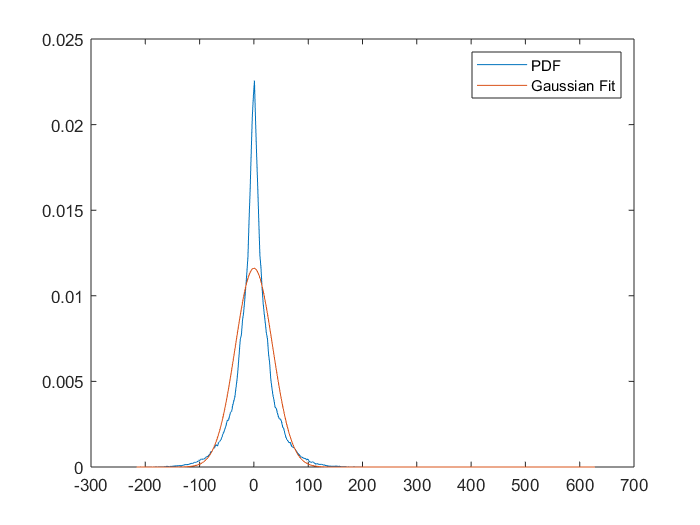

varVx=var(vxAll);
varVy=var(vyAll);
PDFitVx=fitdist(vxAll','Normal');
figure;
plot((edgesV(1:end-1)+edgesV(2:end))/2,PDVx,'DisplayName','PDF');
hold on;
plot(edgesV,PDFitVx.pdf(edgesV),'DisplayName','Gaussian Fit');
legend;

semilog plot

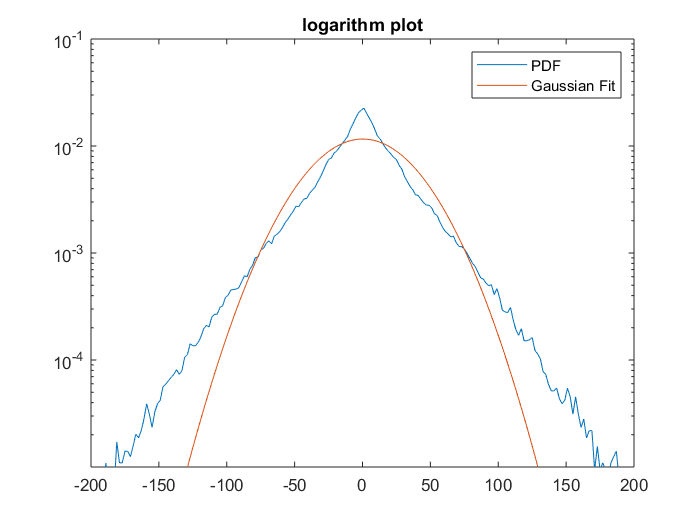

figure;
semilogy((edgesV(1:end-1)+edgesV(2:end))/2,PDVx,'DisplayName','PDF');
hold on;
semilogy(edgesV,PDFitVx.pdf(edgesV),'DisplayName','Gaussian Fit');
legend;
ylim([1e-5,1e-1]);
title("logarithm plot")
hold off;

Looks like an exponential decay on both sides...

Take a look at the spatial distribution of velocity.

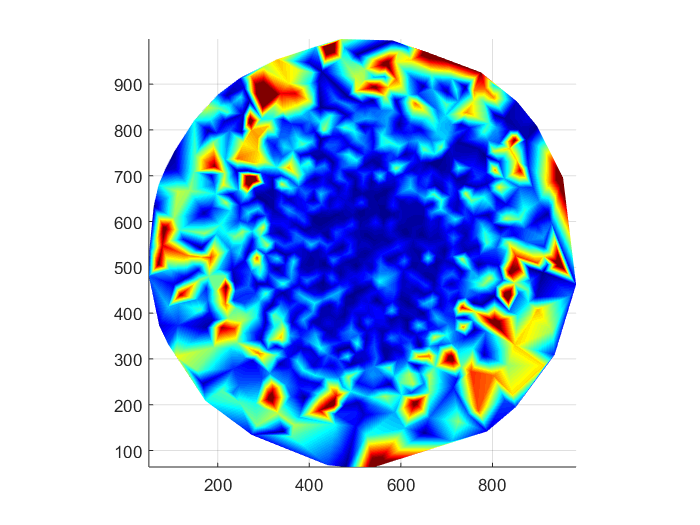

index=100; % the index of the frame.
xSlice=centerArray(index,:,1);
ySlice=centerArray(index,:,2);
tri=delaunay(xSlice,ySlice);
figure;
trisurf(tri,xSlice,ySlice,speed(index,:));
colormap jet;
caxis([0,100*scaling]);
shading interp;
axis equal;
view([0,90]);

Maybe `scatter` is a better idea...

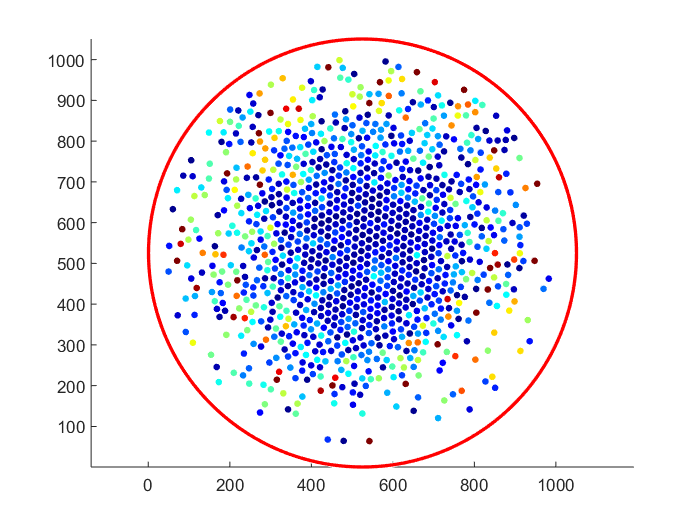

figure;
sidelength=1050/2;
viscircles([sidelength+0.5,sidelength+0.5],sidelength);
hold on;
scatter(xSlice,ySlice,16,speed(index,:),'filled');
colormap jet;
caxis([0,100*scaling]);
axis equal;
hold off;

# Lindemann Ratio $\gamma_m$

# Bond-Orientational Order Parameter

# Shape Factor

# Structure Factor

# Mean Square Displacement

# Scattering Function